# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.7 知乎提问

#### 2.7.16 matlab画图title和坐标轴重合了，怎么把title的位置变高？

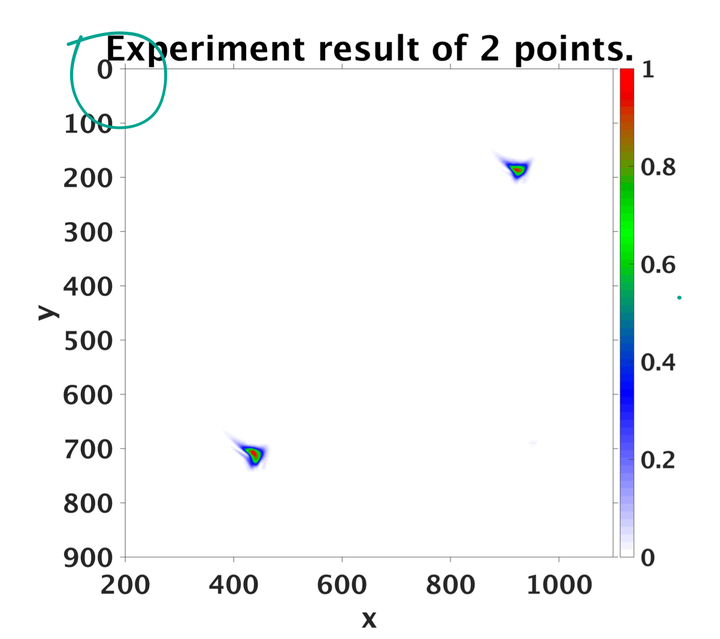

原问题：[https://www.zhihu.com/question/635665019/answer/3397237661](https://www.zhihu.com/question/635665019/answer/3397237661)

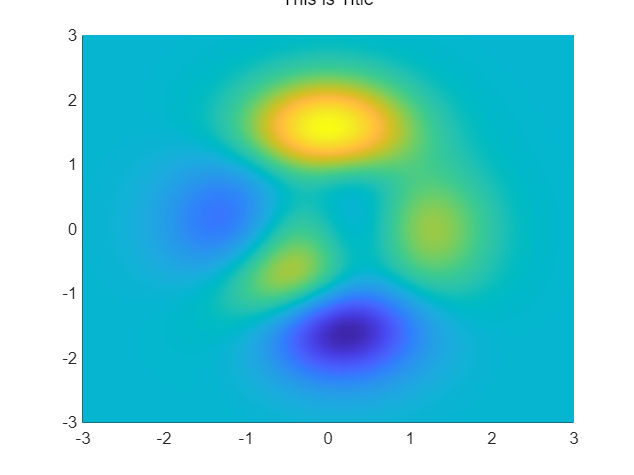

clear;clc;
[x, y, z] = peaks(50);
surf(x, y, z);
view([0, 90]);
shading interp
% 第一种方式
% 标题位置
title('This is Title', 'Position', [0, 3.4, 0]);

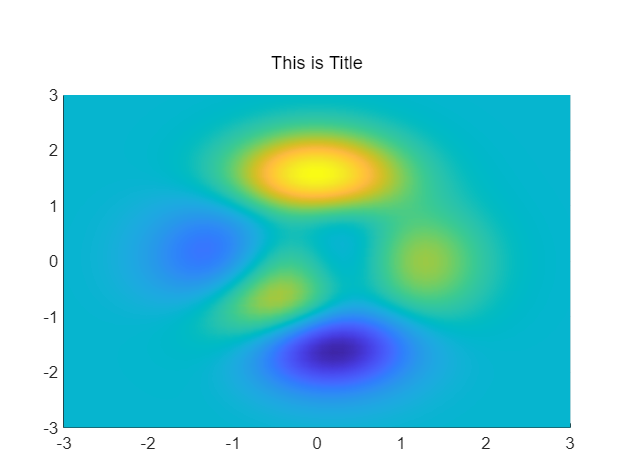

% 第二种方式
% 修改绘图区域位置
figure;
surf(x, y, z);
view([0, 90]);
shading interp
set(gca, 'Position', [0.1, 0.1, 0.8, 0.7]);
title('This is Title', 'Position', [0, 3.4, 0]);